# Importing high-reslution sea surface temperature data with Matlab

The function getSST reads and store the sea surface temperature (SST)  produced on a daily basis by the JPL OurOcean group [1]. The dataset is described in more details in CHao et al. [2]. The SST data are available on a grid of 0.009 degrees, which represent  a horizontal resolution of approximatively  1 km. The second example works with the function borders.m and/or bordersm.m [3,4]

**References**

[1] [https://podaac.jpl.nasa.gov/dataset/JPL_OUROCEAN-L4UHfnd-GLOB-G1SST](https://podaac.jpl.nasa.gov/dataset/JPL_OUROCEAN-L4UHfnd-GLOB-G1SST)

[2] Chao, Y., Z. Li, J. D. Farrara, and P. Huang: Blended sea surface  temperatures from multiple satellites and in-situ observations for  coastal oceans, 2009: Journal of Atmospheric and Oceanic Technology, 26  (7), 1435-1446, 10.1175/2009JTECHO592.1

[3]    Greene, Chad A., et al. “The Climate Data Toolbox for MATLAB.”  Geochemistry, Geophysics, Geosystems, American Geophysical Union (AGU),  July 2019, doi:10.1029/2019gc008392.

[4] https://se.mathworks.com/matlabcentral/fileexchange/50390-borders

 Initialisation

clearvars;close all;clc;
adresse = 'https://podaac-opendap.jpl.nasa.gov/opendap/allData/ghrsst/data/GDS2/L4/GLOB/JPL/MUR/v4.1';

## Get the SST data at single position for multiple days

% Select 13 days for the year 2015
targetDay =1:30:365;  % targetDay should be between 1 and  365
targetYEar = {'2015'};

targetLat = 54; % target latitude
targetLon = 7;  % target longitude
% Preallocation
time = NaT(1,numel(targetYEar)*numel(targetDay));
SST = NaN(1,numel(targetYEar)*numel(targetDay));

% For loop to extract the SST data at (targetLat,targetLon)
oo= 1;
for jj=1:numel(targetYEar)
    for kk=1:numel(targetDay)
        tic
        if targetDay(kk)<10
            myDay = num2str(targetDay(kk));
            myDay = ['00',myDay];
        elseif targetDay(kk)<100 && targetDay(kk)>=10
            myDay = num2str(targetDay(kk));
            myDay = ['0',myDay];
        else
            myDay = num2str(targetDay(kk));
        end
        
        url = [adresse,'/',targetYEar{jj},'/',myDay,'/'];
        fprintf(['target url: ',url,' \n']);
        [filename] = getFilesName(url);
        urldat = [adresse,'/',targetYEar{jj},'/',myDay,'/',filename{1}];
        [SST(oo),~,time(oo)] = collectTemp_NOAA(urldat,targetLat,targetLon);
        oo=oo+1;
        toc
    end
end

target url: https://podaac-opendap.jpl.nasa.gov/opendap/allData/ghrsst/data/GDS2/L4/GLOB/JPL/MUR/v4.1/2015/001/ 


Elapsed time is 13.106262 seconds.


target url: https://podaac-opendap.jpl.nasa.gov/opendap/allData/ghrsst/data/GDS2/L4/GLOB/JPL/MUR/v4.1/2015/031/ 


Elapsed time is 11.124049 seconds.


target url: https://podaac-opendap.jpl.nasa.gov/opendap/allData/ghrsst/data/GDS2/L4/GLOB/JPL/MUR/v4.1/2015/061/ 


Elapsed time is 11.955072 seconds.


target url: https://podaac-opendap.jpl.nasa.gov/opendap/allData/ghrsst/data/GDS2/L4/GLOB/JPL/MUR/v4.1/2015/091/ 


Elapsed time is 11.763922 seconds.


target url: https://podaac-opendap.jpl.nasa.gov/opendap/allData/ghrsst/data/GDS2/L4/GLOB/JPL/MUR/v4.1/2015/121/ 


Elapsed time is 12.694105 seconds.


target url: https://podaac-opendap.jpl.nasa.gov/opendap/allData/ghrsst/data/GDS2/L4/GLOB/JPL/MUR/v4.1/2015/151/ 


Elapsed time is 13.729091 seconds.


target url: https://podaac-opendap.jpl.nasa.gov/opendap/allData/ghrsst/data/GDS2/L4/GLOB/JPL/MUR/v4.1/2015/181/ 


Elapsed time is 12.403797 seconds.


target url: https://podaac-opendap.jpl.nasa.gov/opendap/allData/ghrsst/data/GDS2/L4/GLOB/JPL/MUR/v4.1/2015/211/ 


Elapsed time is 11.576106 seconds.


target url: https://podaac-opendap.jpl.nasa.gov/opendap/allData/ghrsst/data/GDS2/L4/GLOB/JPL/MUR/v4.1/2015/241/ 


Elapsed time is 11.378767 seconds.


target url: https://podaac-opendap.jpl.nasa.gov/opendap/allData/ghrsst/data/GDS2/L4/GLOB/JPL/MUR/v4.1/2015/271/ 


Elapsed time is 19.480038 seconds.


target url: https://podaac-opendap.jpl.nasa.gov/opendap/allData/ghrsst/data/GDS2/L4/GLOB/JPL/MUR/v4.1/2015/301/ 


Elapsed time is 18.704451 seconds.


target url: https://podaac-opendap.jpl.nasa.gov/opendap/allData/ghrsst/data/GDS2/L4/GLOB/JPL/MUR/v4.1/2015/331/ 


Elapsed time is 12.823586 seconds.


target url: https://podaac-opendap.jpl.nasa.gov/opendap/allData/ghrsst/data/GDS2/L4/GLOB/JPL/MUR/v4.1/2015/361/ 


Elapsed time is 11.918926 seconds.


### Display the time series

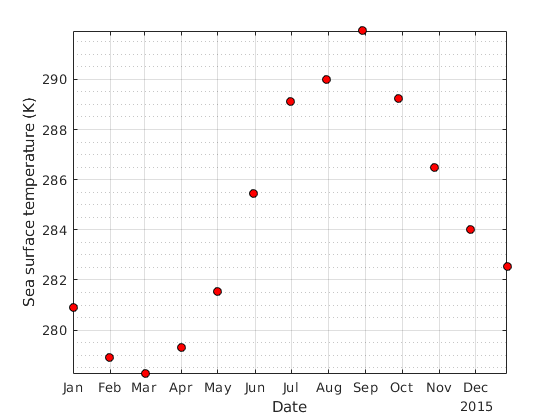

clf;close all;
figure
plot(time,SST,'ko','markerfacecolor','r')
grid on
grid minor
axis tight
xlabel('Date');
ylabel('Sea surface temperature (K)')

set(gcf,'color','w');

## Get the SST data at multiple position for a single day

clearvars;close all;clc;
adresse = 'https://podaac-opendap.jpl.nasa.gov/opendap/allData/ghrsst/data/GDS2/L4/GLOB/JPL/MUR/v4.1';
targetDay =1;
targetYEar = {'2015'};
minLat = 53;
maxLat = 64;
minLon = 4;
maxLon = 14;
targetLat = [minLat,maxLat];  % from minLat to maxLat
targetLon = [minLon,maxLon];   % from minLon to maxLon

for jj=1:numel(targetYEar)
    for kk=targetDay(1):1:targetDay(end)
        tic
        if kk<10
            myDay = num2str(kk);
            myDay = ['00',myDay];
        elseif kk<100
            myDay = num2str(kk);
            myDay = ['0',myDay];
        else
            myDay = num2str(kk);
        end
        url = [adresse,'/',targetYEar{jj},'/',myDay,'/'];
        fprintf(['target url: ',url,' \n']);
        [filename] = getFilesName(url);
        
        % There are 1-2 dataset per day. We choose the first one here
        urldat = [adresse,'/',targetYEar{jj},'/',myDay,'/',filename{1}];
        [SST,lon,lat,mask,time] = getSST(urldat,targetLat,targetLon,'Resolution',0.01);
    end
end

target url: https://podaac-opendap.jpl.nasa.gov/opendap/allData/ghrsst/data/GDS2/L4/GLOB/JPL/MUR/v4.1/2015/001/ 


### Display the SST map

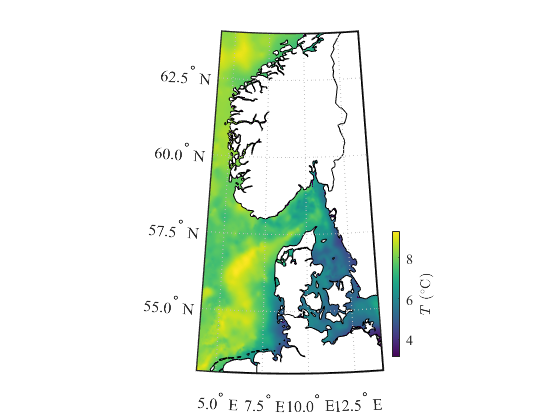

SST(mask==0) = nan; % Apply the mask to remove SST data related to land area
if ~exist('borders.m','file')
    error('The example file uses the functions borders.m and/or bordersm.m by Chad Green. They can be downlaoded here: https://mathworks.com/matlabcentral/fileexchange/50390-borders');
end

if  license('test','MAP_Toolbox')
    clf;close all;
    worldmap(targetLat,targetLon)
    geoshow(lat,lon,SST-273.15, 'DisplayType','texturemap')
    hold on
    bordersm('Norway','facecolor','white')
    bordersm('Sweden','facecolor','white')
    bordersm('Denmark','facecolor','white')
    bordersm('Germany','facecolor','white')
    bordersm('Netherlands','facecolor','white')
    colorbar
else
    
    clf;close all;
    figure
    imagesc(lon(1,:),lat(:,1),SST-273.15);axis xy
    borders('Norway','facecolor','white')
    borders('Sweden','facecolor','white')
    borders('Denmark','facecolor','white')
    borders('Germany','facecolor','white')
    borders('Netherlands','facecolor','white')
    axis equal
    ylim([targetLat])
    xlim([targetLon])
    ylabel('latitude');
    xlabel('Longitude');
end

if exist('viridis.m','file')
    colormap('viridis');
else
    colormap('hot');
end
caxis([min(SST(:)-273.15) max(SST(:)-273.15)])
set(findall(gcf,'-property','FontSize'),'FontSize',12,'FontName','Times')
colorbar off
cb2 = colorbar(gca,'Position',[0.7 0.15 .015 .3]);
cb2.Label.String = '$T$ ($^{\circ}$C)';
cb2.Label.Interpreter = 'latex';
cb2.AxisLocation = 'out';

set(gcf,'color','w')